clc; clear;
format long

%Inputs
latitude=input('Enter Latitude(degrees):'); %Latitude(eg:24.9537°N)
while latitude<-90 || latitude>90|| isnan(latitude)
    disp('Invalid latitude. Latitude must lies between -90 and 90.');
    latitude=input('Enter Latitude(degrees):');
end
longitude=input('Enter Local Longitude(degrees):'); %Local longitude(Longitude: 67.0007°E)
while longitude<-180 || longitude>180 || isnan(longitude)
    disp('Invalid longitude. Longitude must lies between -180 and 180.');
    longitude=input('Enter Longitude (degrees):');
end
rho=0.2; %Ground reflectance 
beta=latitude; %Collector tilt
gamma=0; %Surface faces south

%Day-Month calculations
month=menu('CHOOSE A MONTH','January','February','March','April','May','June','July',...
    'August','September','October','November','December'); 
i=input('Day of Month:'); 
switch month 
    case 1,if i>31, error('The day number is invalid for January'),end,n=i;
    case 2,if i>28, error('The day number is invalid for February'),end,n=31+i;
    case 3,if i>31, error('The day number is invalid for March'),end,n=59+i; 
    case 4,if i>30, error('The day number is invalid for April'),end,n=90+i; 
    case 5,if i>31, error('The day number is invalid for May'),end,n=120+i; 
    case 6,if i>30, error('The day number is invalid for June'),end,n=151+i; 
    case 7,if i>31, error('The day number is invalid for July'),end,n=181+i; 
    case 8,if i>31, error('The day number is invalid for August'),end,n=212+i; 
    case 9,if i>30, error('The day number is invalid for September'),end,n=243+i; 
    case 10,if i>31, error('The day number is invalid for October'),end,n=273+i; 
    case 11,if i>30, error('The day number is invalid for November'),end,n=304+i; 
    case 12,if i>31, error('The day number is invalid for December'),end,n=334+i; 
end

start_time=0; %Start time(midnight)
end_time=23; %End time(11 PM)

% Pre-allocate arrays for hourly values
Hours_of_day=(start_time:end_time)';
ST_arr=NaN(1,24)';              %Solar Time Hours_of_day
omega_arr=NaN(1,24)';           %Hour Angle (deg)
alpha_s_arr=NaN(1,24)';         %Solar Altitude (deg)
theta_z_arr=NaN(1,24)';         %Solar Zenith (deg)
SolarAzimuth_arr=NaN(1,24)';    %Solar Azimuth (deg)
theta_i_arr=NaN(1,24)';         %Angle of Incidence (deg)
m_arr=NaN(1,24)';               %Air Mass ratio
Ib_arr= zeros(1,24)';           %Direct Beam Radiation (W/m^2)-DNI
Ibc_arr=zeros(1,24)';           %Beam Radiation on collector (W/m^2)
Idc_arr=zeros(1,24)';           %Diffuse Radiation on collector (W/m^2)
Irc_arr=zeros(1,24)';           %Reflected Radiation on collector (W/m^2)
Ic_arr=zeros(1,24)';            %Total Radiation on the collector (W/m^2)

%Store results for plotting
time_values=[];
Ic_values=[];

%Constant Calculations
delta=23.45*sind(360*((284+n)/365)); %Declination Angle (δ)
GMT=ceil(longitude/15); %Time zone offset
SL=GMT*15;
B=360/365*(n-81);
EoT=(229.2/60)*(0.000075+0.001868*cosd(B)-0.032077*sind(B)-...
    0.014615*cosd(2*B)-0.04089*sind(2*B)); %Equation of Time in minutes
A=1160+75*sind((360/365)*(n-275));
k=0.174+0.035*sind((360/365)*(n-100));
C=0.095+0.04*sind((360/365)*(n-100));

%Loop Calculations
for time=start_time:end_time
    index=time+1;
    ST=time+(EoT-(4*(SL-longitude))/60);ST_arr(index)=ST; %Solar Time
    omega=(ST-12)*15; omega_arr(index)=omega; %Hour Angle (Each hour=15° movement)
    %Incidence Angle Calculation (Theta_i)
    theta=sind(delta)*sind(latitude)*cosd(beta)-sind(delta)*cosd(latitude)*sind(beta)*...
        cosd(gamma)+cosd(delta)*cosd(latitude)*cosd(beta)*cosd(omega)+...
        cosd(delta)*sind(latitude)*sind(beta)*cosd(gamma)*cosd(omega);
    theta_i=acosd(theta); theta_i_arr(index)=theta_i;
    %Solar Altitude Angle (α)
    alpha_s=asind(cosd(latitude)*cosd(delta)*cosd(omega)+sind(latitude)*sind(delta));
    alpha_s_arr(index)=alpha_s;
    %Solar Zenith Angle (θz)
    theta_z=acosd(cosd(latitude)*cosd(delta)*cosd(omega)+sind(latitude)*sind(delta));
    theta_z_arr(index)=theta_z;
    if alpha_s>0
        %Solar Azimuth Angle (Azimuth)
        SolarAzimuth=sign(omega)*abs(acosd((cosd(theta_z)*sind(latitude)-sind(delta))/...
            (sind(theta_z)*cosd(latitude)))); SolarAzimuth_arr(index)=SolarAzimuth;
        m=1/sind(alpha_s); m_arr(index)=m;%Air Mass Ratio (m)
        Ib=A*exp(-k*m); Ib_arr(index)=Ib; %Direct Beam Radiation
        Ibc=Ib*cosd(theta_i); Ibc_arr(index)=Ibc;%Beam radiation on collector
        Idc=Ib*C*((1+cosd(beta))/2); Idc_arr(index)=Idc; %Diffuse radiation on collector
        Irc=rho*Ib*(sind(alpha_s)+C)*((1-cosd(beta))/2); %Reflected radiation on collector
        Irc_arr(index)=Irc;
        Ic=Ibc+Idc+Irc; Ic_arr(index)=Ic;
    else 
        Ic_arr(index)=0;
    end
    time_values=[time_values;time];
    Ic_values=[Ic_values;Ic_arr(index)];
end

%For Table
variablenames={'Hour','SolarTime','HourAngle','SolarAltitude','SolarZenith',...
    'SolarAzimuth','IncidenceAngle','Air/Mass','IB','IBc','IDc','IRc','IC'};
Table_cal=table(Hours_of_day,ST_arr,omega_arr,alpha_s_arr,theta_z_arr,SolarAzimuth_arr...
    ,theta_i_arr,m_arr,Ib_arr,Ibc_arr,Idc_arr,Irc_arr,Ic_arr,'VariableNames',variablenames);
fprintf('\n\nHourly Data:\n')



Hourly Data:


disp(Table_cal);

    Hour        SolarTime             HourAngle          SolarAltitude        SolarZenith         SolarAzimuth        IncidenceAngle         Air/Mass               IB                 IBc                 IDc                  IRc                  IC       
    ____    __________________    _________________    _________________    ________________    _________________    ________________    ________________    ________________    ________________    ________________    _________________    ________________

      0     -0.581693706666667         -188.725

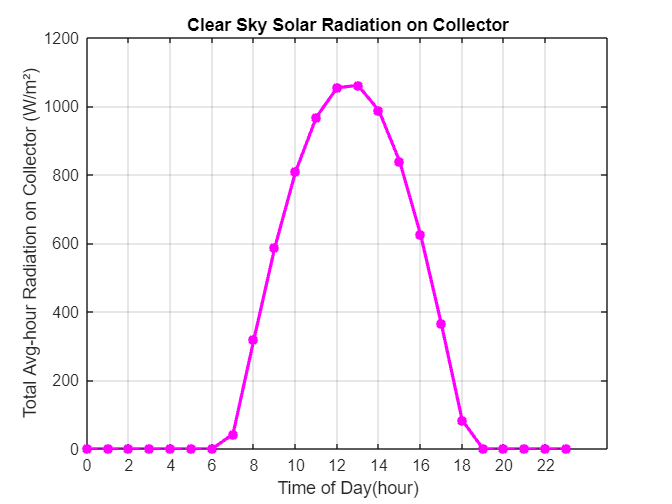


%Plot Results
figure;
plot(time_values, Ic_values,'m*-','LineWidth',2);
xticks(start_time:2:end_time);
xlabel('Time of Day(hour)');
ylabel('Total Avg-hour Radiation on Collector (W/m²)');
title('Clear Sky Solar Radiation on Collector');
grid on;